% Imperial College London
% 2024-25 MRes in Medical Robotics and Instrumentation
% Coursework 01 - Coppelia Tester
% Author: Hongyu Wang

clc;
close all;
clear;

## Configuration

TASK_ID = 3;

switch TASK_ID
    case 2
        joint_trajectory_coppelia = load("task02_angles.csv");
        time_trajectory_coppelia = load("task02_times.csv");
        
    case 3
        joint_trajectory_coppelia = load("task03_angles.csv");
        time_trajectory_coppelia = load("task03_times.csv");
    otherwise
        fprintf("[WARNNING] -- INVALID TASK CHOOSE");
end


## CoppeliaSim Using ZeroMQ

HOST = '127.0.0.1'; % CoppeliaSim IP
PORT = 23000;       % Port CoppeliaSim ZeroMQ is listening on

checkCoppeliaSimConnection(HOST, PORT, 3);

[LOG INFO] -- CoppeliaSim Can be Connected
[LOG INFO] -- CoppeliaSim IP Address 127.0.0.1


% Initialize Remote API Client
simClient = RemoteAPIClient();

% Define joint names and end-effector name
jointNames = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', ...
              '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
eeName = '/Mirobot/Tip';

% Simulate robot in CoppeliaSim
ee_positions_coppelia = simulateRobotCoppeliaSim(joint_trajectory_coppelia, time_trajectory_coppelia, simClient, jointNames, eeName);

[LOG INFO] -- Connecting to CoppeliaSim...
[LOG INFO] -- Simulation started successfully.
[LOG INFO] -- Executing trajectory and recording end-effector positions...
[LOG INFO] -- Simulation stopped.
[LOG INFO] -- End-effector positions recorded.


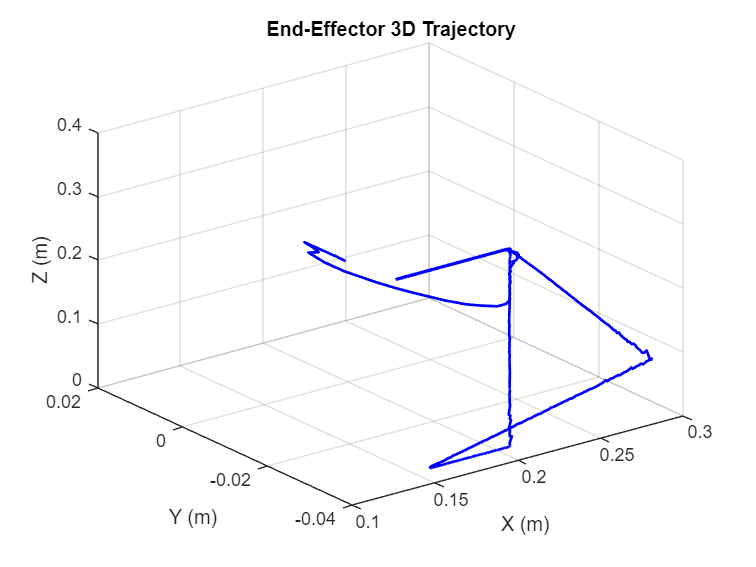

% Plot the 3D trajectory of the end-effector
figure;
plot3(ee_positions_coppelia(:, 1), ee_positions_coppelia(:, 2), ee_positions_coppelia(:, 3), 'b-', 'LineWidth', 1.5);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('End-Effector 3D Trajectory');
grid on;